# Optimization and Data Analytics HW9

## An Introduction to Optimization sec. 10 & 11

## Exercise 10.5

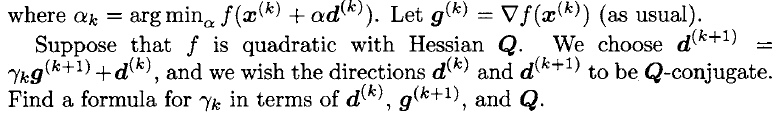

This is the conjugate direction algorithm, which is used for minimizing quadratic functions.

For each iteration, the direction should be Q-conjugate to the previous, meaning the direction vectors should be orthogonal when multiplied by a matrix **Q **so that:


$${\mathit{\mathbf{d}}}^{\left(k\right)T} {\mathit{\mathbf{Q}}\text{\,}\mathit{\mathbf{d}}}^{\left(k+1\right)T} =0$$


Therefore we need to write an expression for ${\mathit{\mathbf{d}}}^{\left(k\right)T} {\mathit{\mathbf{Q}}\text{\,}\mathit{\mathbf{d}}}^{\left(k+1\right)T}$. This is given by the expression for the "next" direction, supplied in the exercise description:


$${\mathit{\mathbf{d}}}^{\left(k+1\right)} =\gamma_k {\mathit{\mathbf{g}}}^{\left(k+1\right)} +{\mathit{\mathbf{d}}}^{\left(k\right)}$$


Then, ${\mathit{\mathbf{d}}}^{\left(k\right)T} {\mathit{\mathbf{Q}}\text{\,}\mathit{\mathbf{d}}}^{\left(k+1\right)T}$ may be rewritten by:


$${{\mathit{\mathbf{d}}}^{\left(k\right)T} {\mathit{\mathbf{Q}}\;\mathit{\mathbf{d}}}^{\left(k+1\right)T} =\mathit{\mathbf{d}}}^{\left(k\right)T} \mathit{\mathbf{Q}}{\left(\gamma_k {\mathit{\mathbf{g}}}^{\left(k+1\right)} +{\mathit{\mathbf{d}}}^{\left(k\right)} \right)}^T =\gamma_k {\mathit{\mathbf{d}}}^{\left(k\right)T} \mathit{\mathbf{Q}}\;{\mathit{\mathbf{g}}}^{\left(k+1\right)} +{\mathit{\mathbf{d}}}^{\left(k\right)T} \mathit{\mathbf{Q}}\;{\mathit{\mathbf{d}}}^{\left(k\right)}$$


$\gamma_k$ must satisfy ${\mathit{\mathbf{d}}}^{\left(k\right)T} {\mathit{\mathbf{Q}}\text{ }\mathit{\mathbf{d}}}^{\left(k+1\right)T} =0$. The expression for ${\mathit{\mathbf{d}}}^{\left(k\right)T} {\mathit{\mathbf{Q}}\text{\,}\mathit{\mathbf{d}}}^{\left(k+1\right)T}$ is therefore solved with regards to $\gamma_k$:


$$\gamma_k =-\frac{{\mathit{\mathbf{d}}}^{\left(k\right)T} {\mathit{\mathbf{Q}}\text{\,}\mathit{\mathbf{d}}}^{\left(k\right)} }{{\mathit{\mathbf{d}}}^{\left(k\right)T} \mathit{\mathbf{Q}}\text{\,}{\mathit{\mathbf{g}}}^{\left(k+1\right)} \text{\,}}$$


## Exercise 10.10

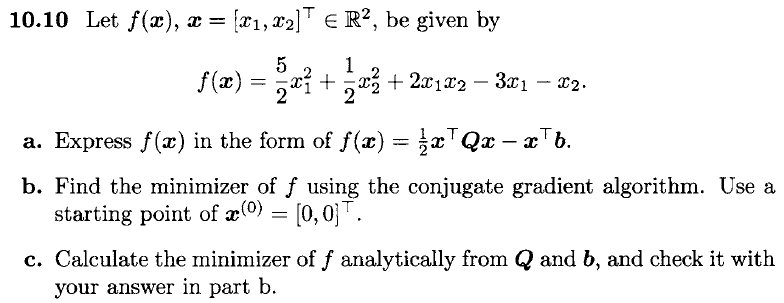

f = @(x1, x2) 5/2*x1^2 + 1/2*x2^2+2*x1*x2-3*x1-x2
x0 = [0; 0];

## a) General Quadratic Form

The quadratic form is formed by the matrix **Q** and the vector **b**.


$$f\left(x_1 ,x_2 \right)=\frac{1}{2}\left\lbrack x_1 \text{ }x_2 \right\rbrack \mathit{\mathbf{Q}}\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack -\left\lbrack x_1 \text{ }x_2 \right\rbrack \mathit{\mathbf{b}}$$


The matrix **Q** is formed by placing the coefficients of the squared $x_1$ and $x_2$ on the diagonal, and dividing the coefficient of the product $x_1 x_2$ by two and placing the result in the upper right corner and lower left corner.


$$Q=\left\lbrack \begin{array}{cc}
\frac{5}{2} & 1\\
1 & \frac{1}{2}
\end{array}\right\rbrack$$


In order to ensure the matrix **Q** is symmetric, it is replaced by:


$$Q_0 =Q_0^T =\frac{1}{2}\left(Q+Q^T \right)$$


Q = [5/2 1;
    1 1/2];
Q = Q+Q'    % the 1/2 multiplier is applied in the final expression

The **b **vector is constructed from the coefficients of the variable $x_1$ and $x_2$. The variables are multiplied by -1, to switch the sign of the variables since **b** is subtracted in the general quadratic form: ALWAYS MULTIPLY BY -1 !!!


$$b=\left\lbrack \begin{array}{c}
-3\\
-1
\end{array}\right\rbrack \ast -1=\left\lbrack \begin{array}{c}
3\\
1
\end{array}\right\rbrack$$


b = [3; 1]

Constructing the quadratic form:


$$f\left(x_1 ,x_2 \right)=\frac{1}{2}\left\lbrack x_1 \text{\,}x_2 \right\rbrack \mathit{\mathbf{Q}}\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack -\left\lbrack x_1 \text{\,}x_2 \right\rbrack \mathit{\mathbf{b}}=\left\lbrack x_1 \text{\,}x_2 \right\rbrack \left\lbrack \begin{array}{cc}
\frac{5}{2} & 1\\
1 & \frac{1}{2}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack -\left\lbrack x_1 \text{\,}x_2 \right\rbrack \left\lbrack \begin{array}{c}
3\\
1
\end{array}\right\rbrack$$


f = @(x1,x2) [x1 x2]*Q*[x1; x2] - [x1 x2]*b

## b) Conjugate Gradient Algorithm

The conjugate gradient algorithm will converge at the minimizer of a quadratic function in $R^D$ in *d* searches along mutually conjugate directions.

Since $f\left(\left\lbrack x_1 x_2 \right\rbrack \right)\in R^2$, the algorithm will require two iterations.

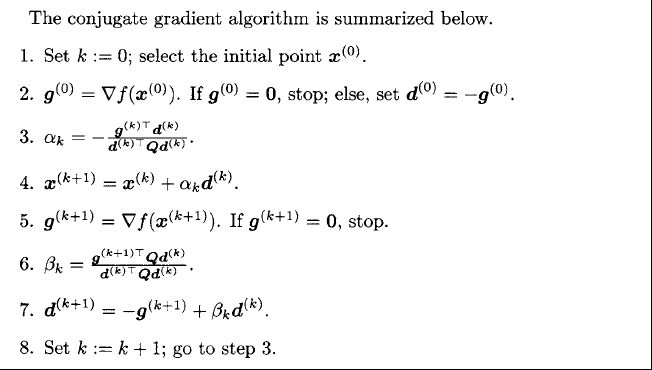

The first step is dtermining an expression for the gradient of *f*:

syms x1 x2
Df = [diff(f,x1) diff(f,x2)]
gradient = matlabFunction(Df)

The algorithm is then initialized and applied:

% Initialize algorithm
g = zeros(2,2);
d = zeros(2,2);
x = zeros(2,3);
g(:,1) = gradient(x0(1),x0(2))';
d(:,1) = -g(:,1);
x(:,1) = x0;
fprintf('Conjugate Gradient Descent Algorithm :\n');
x0

% Perform iterations
for i=1:2
    fprintf('Iteration %d:\n',i);
    % Calculate alpha 
    a_k = -(g(:,i)'*d(:,i))/(d(:,i)'*Q*d(:,i))
    x(:,i+1) = x(:,i)+a_k*d(:,i)
    g(:,i+1) = gradient(x(1,i+1),x(2,i+1))
    b_k = (g(:,i+1)'*Q*d(:,i))/(d(:,i)'*Q*d(:,i))
    d(:,i+1) = -g(:,i+1)+b_k*d(:,i)
end

The minimizer is then found as:

min = x(:,3)

## c) Analytical Minimizer

The analytical minimizer of a quadratic function is given by:


$$x^\ast  ={\mathit{\mathbf{Q}}}^{-1} \mathit{\mathbf{b}}$$


This requires **Q** be invertible, which is the reason for constructing **Q** as a symmetric matrix.

x_min = inv(Q)*b

## Exercise 11.2